clc
clear
close all

Basic first order response plot

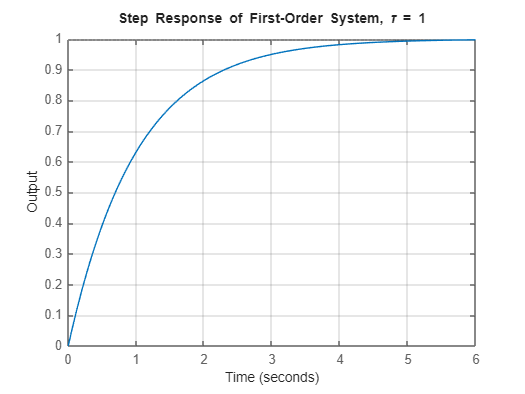

tau = 1;    % Time constant

% Define transfer function
gain = 1;   % TF gain
char_eqn = [1, tau];    % Characteristic equation
sys = tf(gain, char_eqn);

% Plot step response
figure;
step(sys);
title(['Step Response of First-Order System, \tau = ' num2str(tau)]);
xlabel('Time');
ylabel('Output');
grid on;

Examining behavior of changing time constant

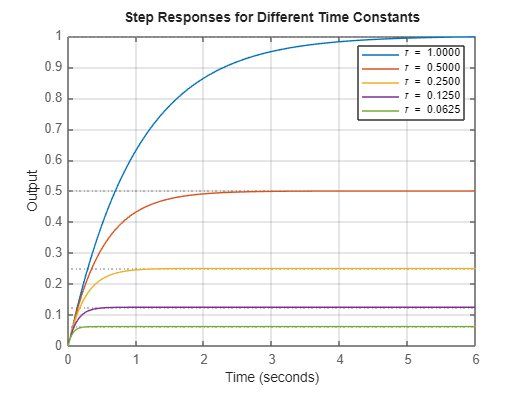

tau = [1 0.5 0.25 0.125 0.0625];
figure;

legendEntries = cell(1, length(tau));

for i = 1:length(tau)
    gain = 1;
    char_eqn = [1, 1/tau(i)];
    sys = tf(gain, char_eqn);
    step(sys);
    hold on;
    legendEntries{i} = sprintf('\\tau = %.4f', tau(i));
end

title('Step Responses for Different Time Constants');
xlabel('Time');
ylabel('Output');
grid on;
legend(legendEntries);
hold off;